Textfile = load("STM32Output.txt")

Textfile =    -0.0300
    0.0100
   -0.0400
    0.0500
   -0.0300
   -0.0200
    0.0600
   -0.0300
   -0.0100
    0.0500


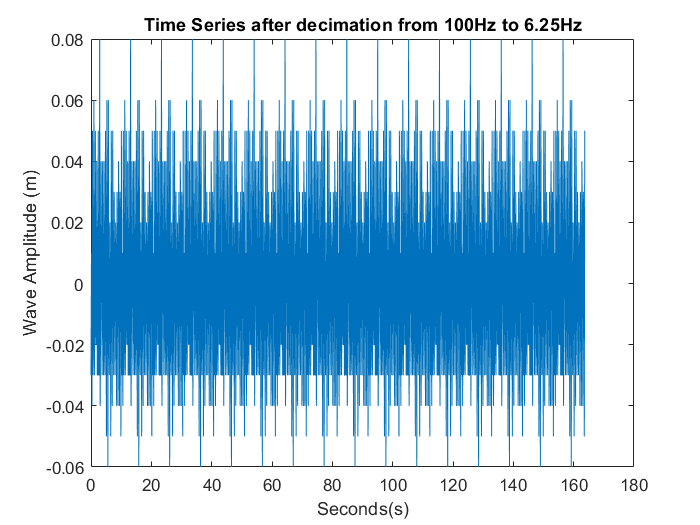

writematrix(Textfile, "STM32Output.csv");
timeSeriesData = readtable("STM32Output.csv");


N =  2048 - 1; 
timeSeriesData = timeSeriesData{:, 1}; %data is symmetric, *2 to account for contribution of other half 
fs = 6.25;
time = 1/fs*(0:(N));

plot(time(1:1024), timeSeriesData(1:1024)); %only plotting the real side of the dataset 
title("Time Series after decimation from 100Hz to 6.25Hz");
xlabel("Seconds(s)");
ylabel("Wave Amplitude (m)");